This script illustrates how basal gaps are invalidated between data gaps in the raw data.

%create test basal data with a significant gap
gap = hours(6);
timestamps = datetime("today")+hours([0,1,2,4,12,14,16,23])

timestamps = 1×8 datetime array
   23-Oct-2025 00:00:00   23-Oct-2025 01:00:00   23-Oct-2025 02:00:00   23-Oct-2025 04:00:00   23-Oct-2025 12:00:00   23-Oct-2025 14:00:00   23-Oct-2025 16:00:00   23-Oct-2025 23:00:00


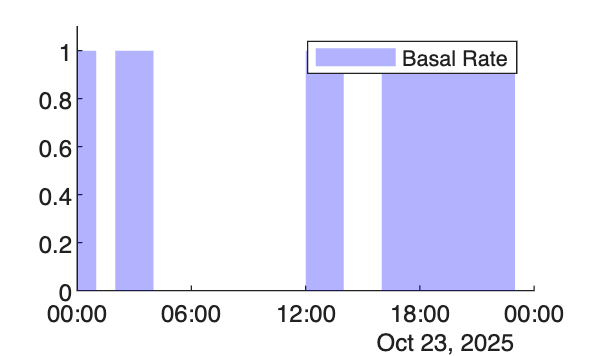

basal_rates = ones(length(timestamps),1)';basal_rates(2:2:end)=0; 
tt = timetable(timestamps', basal_rates', 'VariableNames', {'basal_rate'});

clf; hold on;
[xs, ys] = stairs(tt.Properties.RowTimes, tt.basal_rate);
area(xs ,ys ,'FaceAlpha', 0.3, 'EdgeColor', 'none','FaceColor','blue',DisplayName='Basal Rate');
%scatter(tt.Properties.RowTimes, tt.basal_rate,"^","MarkerFaceColor","blue",MarkerEdgeColor="none",DisplayName='Basal Rate Change')
ylim([0, max(tt.basal_rate) + 0.1])
legend()

Resample basal data

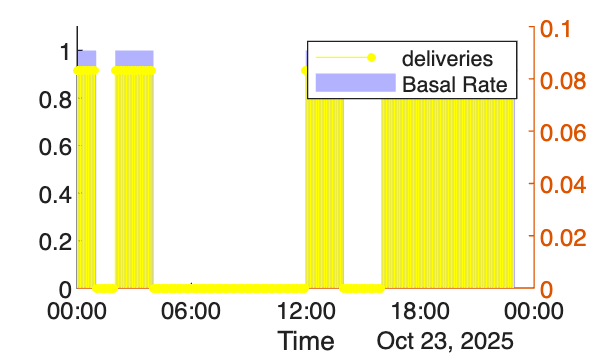

ttResampled = AIDIF.interpolateBasal(tt);

yyaxis('right')
stem(ttResampled,"Time","InsulinDelivery",Color='yellow',Marker='.',MarkerSize=10,DisplayName='deliveries')

Calculate valid flags

valid = AIDIF.findGaps(tt,ttResampled,2);
isequal(tt.Time, ttResampled.Time) %sanity check

ans = logical
   0


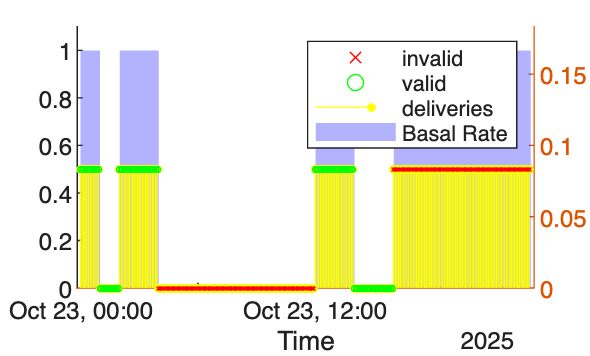

ttResampled.Valid = valid.Valid;

% Highlight Nans
valid = ttResampled.Valid; % Create a shorthand for the logical array
scatter(ttResampled.Time(valid ), ttResampled.InsulinDelivery(valid), 5,'o','MarkerEdgeColor','green',DisplayName='valid')
scatter(ttResampled.Time(~valid ), ttResampled.InsulinDelivery(~valid), 5,'x','MarkerEdgeColor','red',DisplayName='invalid')
ylim([0,5/60+0.1])
xlim([min(tt.Time) - minutes(10), max(tt.Time) + minutes(10)]);
hold off